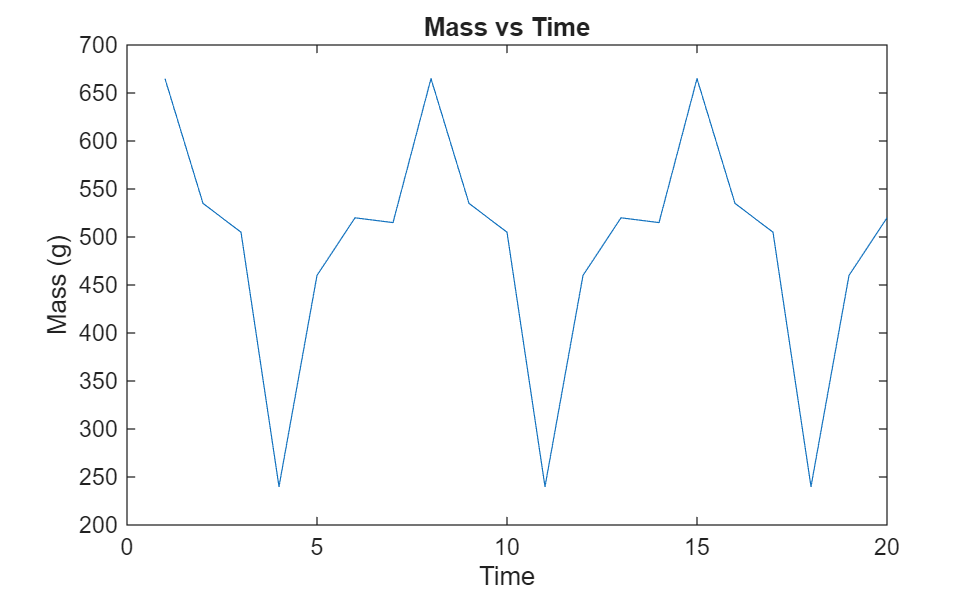

%ALL FOOD ITEMS

% [mass; calories; Protein; fat; carbs] 

% Food A: Chia seeds
FoodA = [1; 4.86; 0.17; 0.31; 0.42]; % per g

% Food B: Spirulina
FoodB = [1; 2.9; 0.57; 0.08; 0.24];

% Food C: Chlorella
FoodC = [1; 4.0; 0.58; 0.12; 0.23];

% Food D: Oyster mushrooms
FoodD = [1; 0.33; 0.033; 0.004; 0.06];

% Food E: Lion's mane mushrooms
FoodE = [1; 0.35; 0.02; 0.005; 0.07];

% Food F: Crickets (dried)
FoodF = [1; 4.8; 0.65; 0.20; 0.10];

% Food G: Mealworms (dried)
FoodG = [1; 5.0; 0.50; 0.30; 0.10];



% DIET 1 (Days 1–7)
Day1_1 = [FoodA*50, FoodB*30, FoodC*15, FoodD*250, FoodE*200, FoodF*40, FoodG*80];
Day2_1 = [FoodA*20, FoodB*35, FoodC*10, FoodD*350, FoodF*40, FoodG*80];
Day3_1 = [FoodA*40, FoodB*35, FoodC*10, FoodD*350, FoodF*70];
Day4_1 = [FoodA*20, FoodB*50, FoodC*20, FoodE*100, FoodF*50];
Day5_1 = [FoodA*20, FoodB*45, FoodC*15, FoodD*300, FoodG*80];
Day6_1 = [FoodA*15, FoodB*25, FoodD*150, FoodE*200, FoodF*70, FoodG*60];
Day7_1 = [FoodA*35, FoodB*40, FoodD*150, FoodE*200, FoodG*90];

Diet1 = [Day1_1, Day2_1, Day3_1, Day4_1, Day5_1, Day6_1, Day7_1];



N = 20;
mass = zeros(1,N); calories = zeros(1,N); protein = zeros(1,N); fat = zeros(1,N); carbs = zeros(1,N);

for t = 1:N
    day_idx = mod(t-1,7) + 1;      % 1,2,3,4,5,6,7,1,2,3,...
    current_day = Days{day_idx}; 

    daily_total = sum(current_day, 2);   % sum each row across foods
    mass(t)     = daily_total(1);
    calories(t) = daily_total(2);
    protein(t)  = daily_total(3);
    fat(t)      = daily_total(4);
    carbs(t)    = daily_total(5);
end



%Conditions
%----------------------------------
%Picking arbitrary Mass
%Each day subtracts from the mass amount, eventually running out






%Conditions
%----------------------------------
%Each data point should be correct within range:
%Calories between: range
%Protein
%Fat
%Carbs

%if not there is a buffer - yellow range

%if outside that range, red

%Figure out how many days in red they can be and then die







%Results

time = 1:N;

figure;
plot(time, mass);
xlabel('Time');
ylabel('Mass (g)');
title('Mass vs Time');

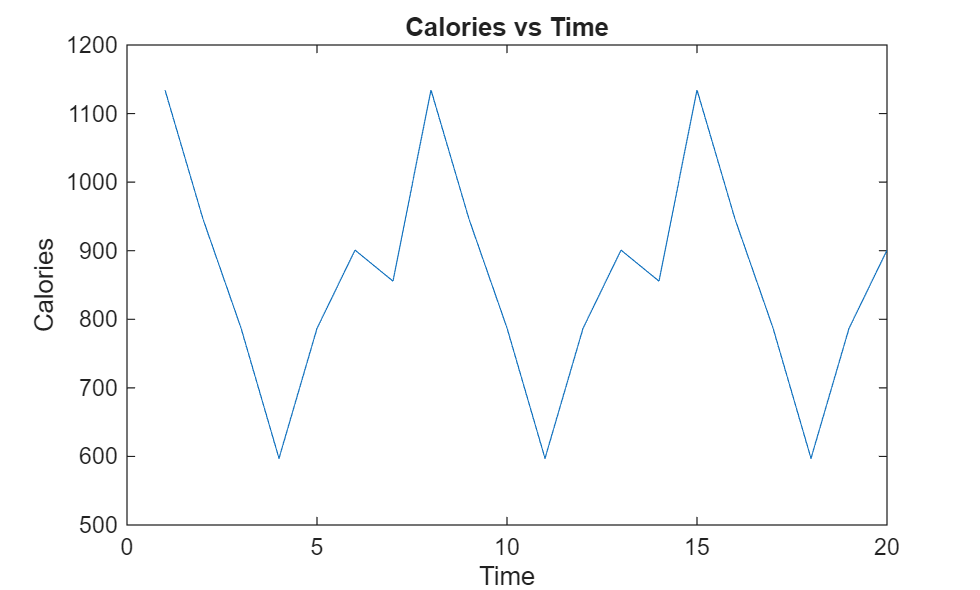


figure;
plot(time, calories);
xlabel('Time');
ylabel('Calories');
title('Calories vs Time');

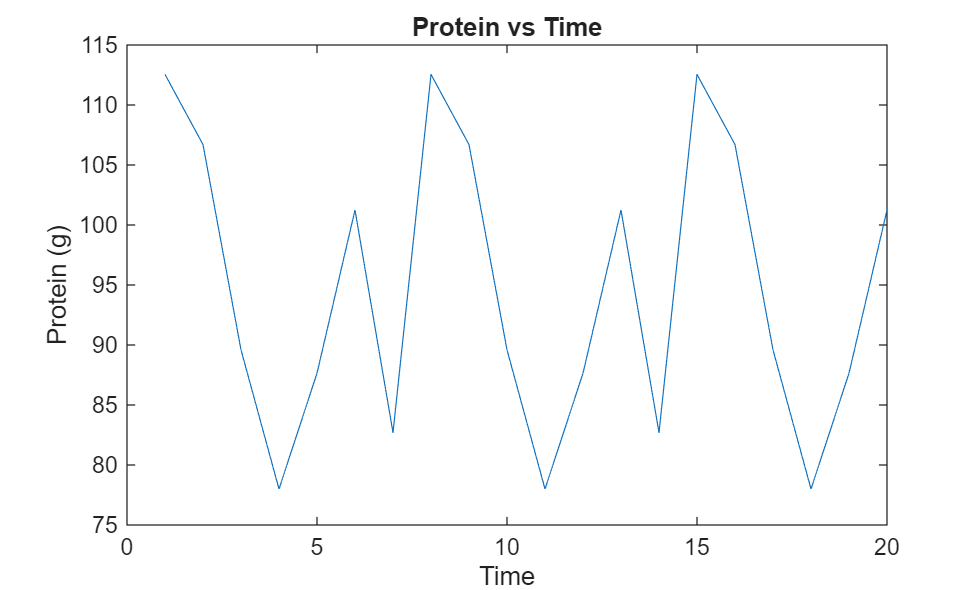


figure;
plot(time, protein);
xlabel('Time');
ylabel('Protein (g)');
title('Protein vs Time');

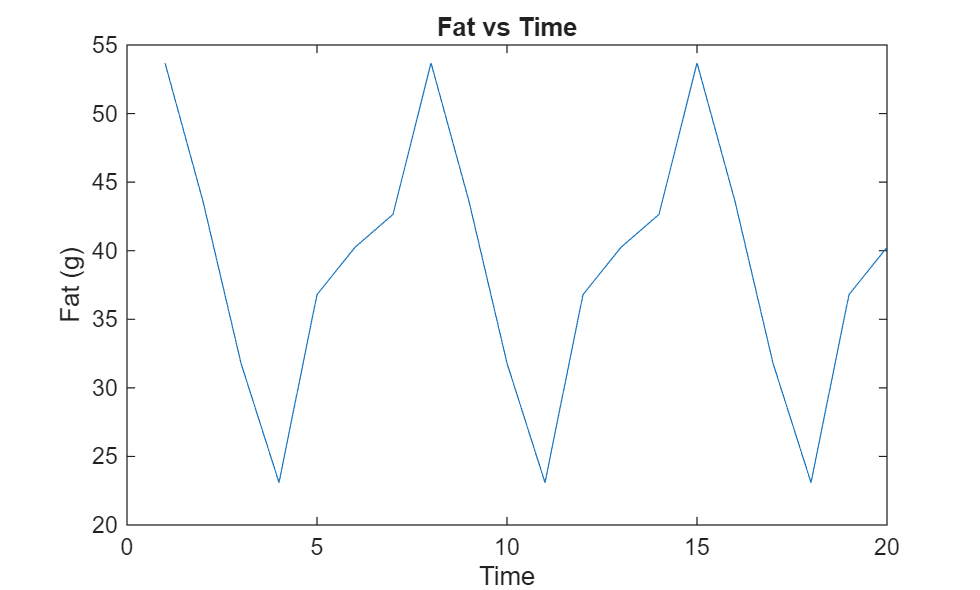


figure;
plot(time, fat);
xlabel('Time');
ylabel('Fat (g)');
title('Fat vs Time');

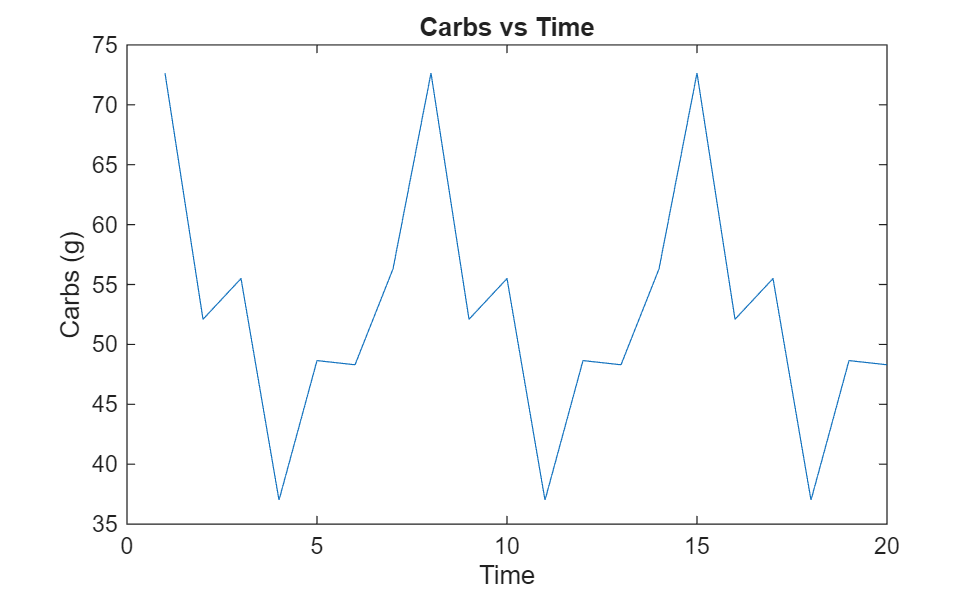


figure;
plot(time, carbs);
xlabel('Time');
ylabel('Carbs (g)');
title('Carbs vs Time');